# Template of Manipulator Short project: Skull tumor surgery

**List of to do:**

The Robotic environment must contain:

1.-  **Taula d'operacions: **L'entorn de treball está compost per una** taula principal** de dimensions 1.2 x 1.6 m on es col·loca al pacient  i una **taula auxiliar** de 50cmx50cm on hi estarà el Puma. Per defecte la taula principal esta inclinada 30º y la taula auxiliar sempre esta connectada a l'extrem superior.

Dimensions inicials de les taules

clc;
clear;
close all;
mainTableW = 1.2; % amplada de la taula pricipal
mainTableH = 1.6; % llargada de la taula pricipal
auxTableW = 0.5; % amplada de la taula auxiliar
auxTableH = 0.5; % llargada de la taula auxiliar

Parametres de posició inicial. En aquest cas, considerarem que 

mainTablePositionX = 0;
mainTablePositionY = 0;
mainTablePositionZ = 0; % elevació de la taula principal
mainTableTilingDegrees = 0;
mainTableTilingZOffset = mainTableH * tan(deg2rad(mainTableTilingDegrees));
mainTablePosition = [mainTablePositionX mainTablePositionY+mainTableH/2 mainTablePositionZ];

auxTableTilingDegrees = 0;
auxTableTilingZOffset = auxTableH * tan(deg2rad(auxTableTilingDegrees));
auxTableYOffset = (mainTableH/2)-auxTableH/2;
auxTableXOffset = (mainTableW/2)+auxTableW/2;
auxTablePosition = [auxTableXOffset auxTableYOffset mainTableTilingZOffset] + mainTablePosition;

mainTablePoints = getTablePointsMatrixFromCentre(mainTablePosition, mainTableW, mainTableH, mainTableTilingZOffset)

mainTablePoints =    -0.6000    0.6000    0.6000   -0.6000
         0         0    1.6000    1.6000
         0         0         0         0


auxTablePoints = getTablePointsMatrixFromCentre(auxTablePosition, auxTableW, auxTableH, auxTableTilingZOffset)

auxTablePoints =     0.6000    1.1000    1.1000    0.6000
    1.1000    1.1000    1.6000    1.6000
         0         0         0         0


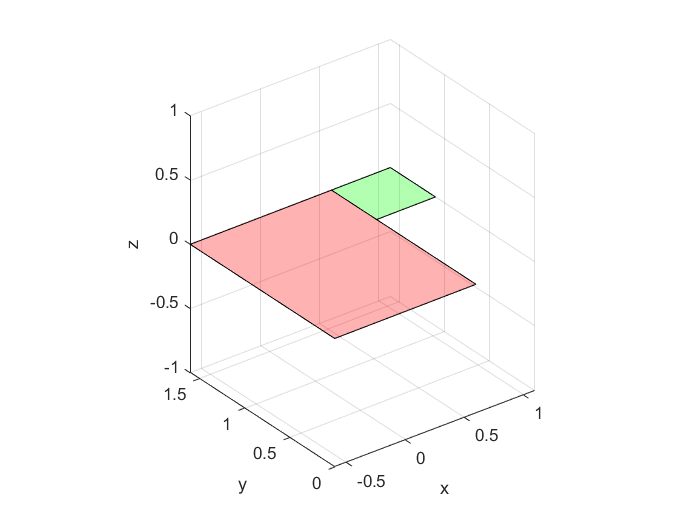

mainTableFigureId = 30;
auxTableFigureId = 40;
% figure;

drawTable(mainTablePoints, 'r');
hold on
drawTable(auxTablePoints, 'g');
axis equal
grid
xlabel('x')
ylabel('y')
zlabel('z')

2.- A 3D model of a human body on the operating table. Use the Workspace given, or other you might find.

*Add your comemnts here..... be concise*

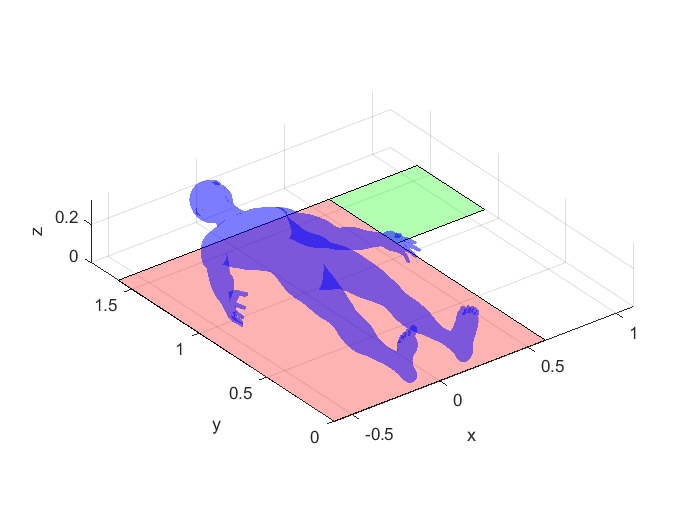

[V,F] = readOBJ('Human_body.obj','Quads',true);
 % Turn triangles into degenerate quads 
humanbodyh = max(V(:,2));
V = V./humanbodyh;
V = V.*1.8;
humanbodyh = max(V(:,2)) - min(V(:,2));
humanbodyw = max(V(:,1)) - min(V(:,1));
humanbodyd = max(V(:,3)) - min(V(:,3));
V(:,3) = V(:,3) + humanbodyd/2;
patch('Faces',F,'Vertices',V,'FaceColor','blue', 'FaceAlpha',.3, 'EdgeColor', 'none');

3.- A human skull model, embedded in the head of the human. Place the fiducials.

*Add your comemnts here.....be concise*

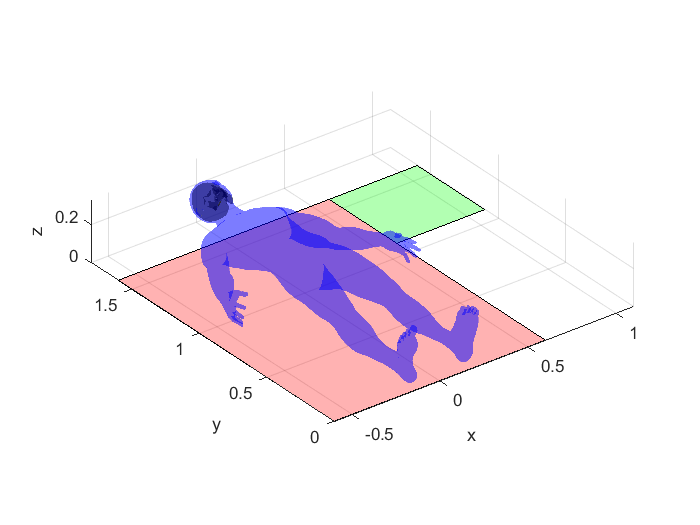

[VS,FS] = readOBJ('Skull.obj');
% make the skull smaller
skullh = max(VS(:,3)) - min(VS(:,3));
VS = VS./skullh;
VS = [VS(:,1).*0.19 VS(:,2).*0.165 VS(:,3).*0.215];
totalVerticesS = size(VS,1);
onesMat = ones(totalVerticesS, 1);
NV = [VS onesMat]';
% skulld = max(VS(:,2)) - min(VS(:,2));
% Rotation and translation
NV = trotx(-90,'deg') * transl(0,-0.155,1.575) * NV;
VS = NV(1:3,:)';
patch('Faces',FS,'Vertices',VS,'FaceColor','black', 'FaceAlpha',.3, 'EdgeColor', 'none');

4.- Use the Dicom images to get the points of the outer perimeter of the tumor relative to some reference frame located in the human skull.

*Add your comemnts here.....be concise*

*Punts del tumor*

VT = [
    -0.0017954 -0.003854 0.0364;
-0.0012784 0.001786 0.035;
-0.006392 -0.0048598 0.035;
-0.0015322 -0.0102178 0.035;
0.0010246 -0.0051136 0.035;
-0.002303 0.0025474 0.0336;
-0.0084318 -0.0056212 0.0336;
-0.001786 -0.0120132 0.0336;
0.0030644 -0.0053674 0.0336;
-0.0015322 0.0038164 0.0322;
-0.0107348 -0.0061288 0.0322;
-0.0015322 -0.0125208 0.0322;
0.0053674 -0.0053674 0.0322;
-0.0020492 0.0045966 0.0308;
-0.0127746 -0.0066364 0.0308;
-0.0015322 -0.0148144 0.0308;
0.0063826 -0.0045966 0.0308;
-0.0025568 0.0056212 0.0294;
-0.0143068 -0.0053674 0.0294;
-0.0048598 -0.0189034 0.0294;
0.0068996 -0.0048598 0.0294;
-0.0020492 0.0063826 0.028;
-0.0145606 -0.005875 0.028;
-0.005875 -0.0201818 0.028;
0.0068996 -0.0043428 0.028;
-0.0028106 0.0081686 0.0266;
-0.0150776 -0.0071534 0.0266;
-0.0071534 -0.0206988 0.0266;
0.0071534 -0.0051136 0.0266;
-0.0033182 0.0104716 0.0252;
-0.0155852 -0.0061288 0.0252;
-0.0061288 -0.0191572 0.0252;
0.0074072 -0.0048598 0.0252;
-0.0038352 0.0109792 0.0238;
-0.0160928 -0.0038352 0.0238;
-0.0040984 -0.0196742 0.0238;
0.007661 -0.0045966 0.0238;
-0.0048598 0.0125114 0.0224;
-0.0171174 -0.0051136 0.0224;
-0.0025662 -0.0206988 0.0224;
0.0130284 -0.0048598 0.0224;
-0.0047658 0.0127746 0.021;
-0.0173712 -0.0053674 0.021;
-0.0043428 -0.0204356 0.021;
0.0143068 -0.0048598 0.021;
-0.0045966 0.0127746 0.0196;
-0.017625 -0.0048598 0.0196;
-0.0053674 -0.0212064 0.0196;
0.015322 -0.005875 0.0196;
-0.0040984 0.0120038 0.0182;
-0.0186496 -0.0048598 0.0182;
-0.0020492 -0.0209526 0.0182;
0.015322 -0.0053674 0.0182;
-0.0043428 0.0122576 0.0168;
-0.0191572 -0.004089 0.0168;
-0.002303 -0.0204356 0.0168;
0.014053 -0.0056212 0.0168;
-0.0030644 0.0114962 0.0154;
-0.0186496 -0.0051136 0.0154;
-0.0025662 -0.0204356 0.0154;
0.0125114 -0.0056212 0.0154;
-0.0030644 0.0120038 0.014;
-0.0191572 -0.0045966 0.014;
-0.0025662 -0.0201818 0.014;
0.0107254 -0.0048598 0.014;
-0.002303 0.01175 0.0126;
-0.0189034 -0.0048598 0.0126;
-0.0020492 -0.0204356 0.0126;
0.0097102 -0.004089 0.0126;
-0.0025662 0.0109792 0.0112;
-0.018142 -0.0043428 0.0112;
-0.002303 -0.0201818 0.0112;
0.0097102 -0.0023124 0.0112;
-0.0030644 0.009964 0.0098;
-0.0178882 -0.0051136 0.0098;
-0.002303 -0.0191572 0.0098;
0.0097102 -0.0028106 0.0098;
-0.002303 0.009964 0.0084;
-0.017625 -0.0048598 0.0084;
-0.0007708 -0.0173712 0.0084;
0.0089394 -0.0015322 0.0084;
-0.0020492 0.0102178 0.007;
-0.0163466 -0.0035814 0.007;
-0.0010246 -0.0166098 0.007;
0.0086856 -0.0007708 0.007;
-0.002303 0.0097008 0.0056;
-0.015839 -0.0028106 0.0056;
-0.0020492 -0.0150776 0.0056;
0.0074072 -0.0015322 0.0056;
-0.0020492 0.0094376 0.0042;
-0.0130284 -0.0015322 0.0042;
-0.0010246 -0.01175 0.0042;
0.0063826 -0.0012784 0.0042;
-0.0025662 0.007661 0.0028;
-0.0094564 -0.0030644 0.0028;
0.0005076 -0.0107348 0.0028;
0.0053674 -0.0010246 0.0028;
-0.000517 0.0071534 0.0014;
-0.0053674 -0.0007708 0.0014;
0.0010246 -0.0074072 0.0014;
0.0043428 -0.0007708 0.0014;
0 0 0;
    ];

*First approach:  Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

5.- Display all necessary Reference Frames

*Add your comemnts here.....be concise*

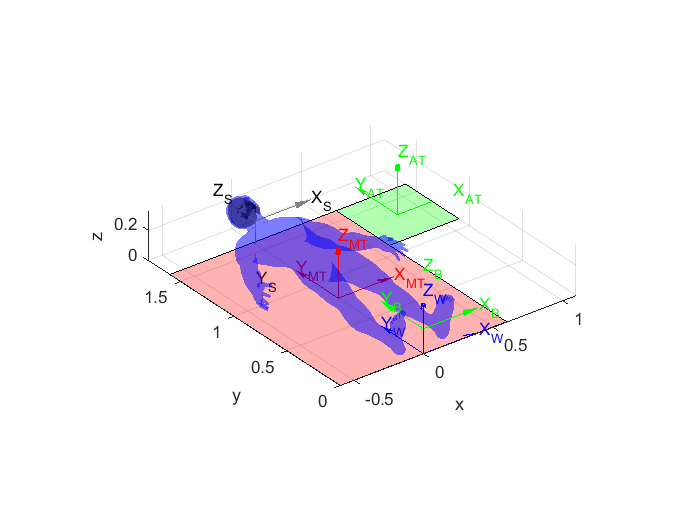

W = eye(4);
trplot(W, 'frame','W','text_opts',{'FontSize', 10},'arrow','color', 'b','thick',1,...
          'width', 1,'length',0.4 )
MT = transl(mainTablePosition)*W;
trplot(MT, 'frame','MT','text_opts',{'FontSize', 10},'arrow','color', 'r','thick',1,...
          'width', 1,'length',0.4 )
AT = transl(auxTablePosition)*W;
trplot(AT, 'frame','AT','text_opts',{'FontSize', 10},'arrow','color', 'g','thick',1,...
          'width', 1,'length',0.4 )
B = transl([0 0 humanbodyd/2]) * W;
trplot(B, 'frame','B','text_opts',{'FontSize', 10},'arrow','color', 'g','thick',1,...
          'width', 1,'length',0.4 )
S = trotx(-90,'deg') * transl(0,-0.155,1.575) * W;
trplot(S, 'frame','S','text_opts',{'FontSize', 10},'arrow','color', 'black','thick',1,...
          'width', 1,'length',0.4 )

6.- Place the 6R Robot manipulator nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

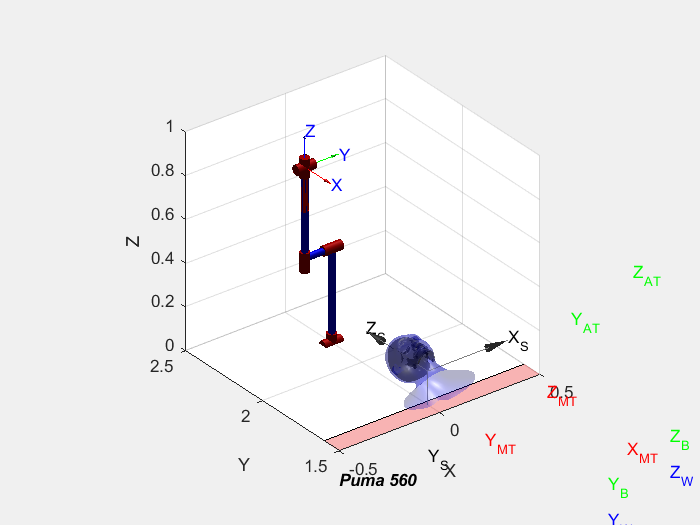

mdl_puma560
RFR = transl(0, 2.2, 0) * trotz(-90, 'deg');
p560.tool = SE3(0, 0, 0.2);
p560.base = RFR;
axis ([-0.5 0.5 1.5 2.5 0 1])
p560.plot(qr, 'zoom', 3)

7.- Get the transformation that maps tumor points in Robot Frame.

*Add your comemnts here.....be concise*

totalVerticesT = size(VT,1);
onesMat = ones(totalVerticesT, 1);
NVT = [VT onesMat]';
% Rotation and translation
skullh = max(VS(:,2));
skullw = min(VS(:,1));
skulld = min(VS(:,3));
tumorh = max(VT(:,3)) - min(VT(:,3));
NVT = trotx(-90,'deg') * transl(skullw+0.06,-skulld-0.120,skullh-tumorh-23*0.0014) * NVT;
VT = NVT(1:3,:)';

8.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

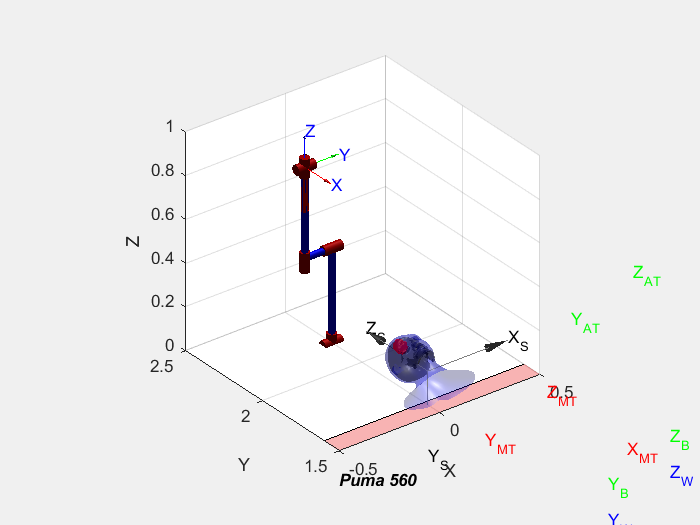

s = scatter3(VT(:,1),VT(:,2),VT(:,3), 20,'filled', 'MarkerFaceColor','red');

9.- Prepare a script that perform a biopsy. Zoom in the scene

*Add your comemnts here.....be concise*

%

10.- Prepare a script that perform trepanation.

*Add your comemnts here.....be concise*

%% put your code Here

11.- Prepare a script that perform tumor burning with the laser.

*Add your comemnts here.....be concise*

%% put your code Here

*Second approach:**  Assume that the ZX plane of the Robot is not aligned with plane of symetry of the human body and it is needed a orientation calibration.*

12.-Get the transformation that maps tumor points in Robot Frame. See teacher help: Triangle.mlx

*Add your comemnts here.....be concise*

%% put your code Here

13.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

%% put your code Here

14.-Use the script that perform a biopsy. Zoom in the scene

*Add your comemnts here.....be concise*

%% put your code Here

15.- Use the  script that perform trepanation.

*Add your comemnts here.....be concise*

%% put your code Here

16.- Use the script that perform tumor burning with the laser.

*Add your comemnts here.....be concise*

%% put your code Here

## Auxiliar Functions

Funcions auxiliars

function drawTable(tablePointsMatrix,tableColor)
tablePolygonX = tablePointsMatrix(1,:);
tablePolygonY = tablePointsMatrix(2,:);
tablePolygonZ = tablePointsMatrix(3,:);
fill3(tablePolygonX,tablePolygonY,tablePolygonZ,tableColor);
alpha 0.3;
end

function tablePoints = getTablePointsMatrixFromCentre(centrePoint,tableWidth,tableHeigth,tilingOffset)
dx = tableWidth/2;
dy = tableHeigth/2;
dz = tilingOffset;
centrePointsAs4x3Matrix = repmat(centrePoint ,4,1);
tablePointsAs4x3Matrix = [-dx -dy 0;dx -dy 0; dx dy dz; -dx dy dz];
tablePointsFromCentre = centrePointsAs4x3Matrix + tablePointsAs4x3Matrix;
tablePoints = tablePointsFromCentre';
end